number = 1e3;
h = 2*10/number

h =    0.020000000000000


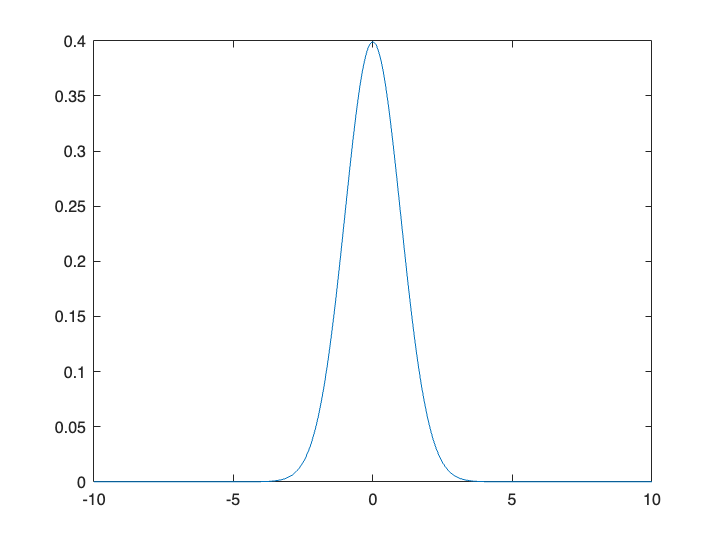

x = -10:h:10;
u = 0;
s = 1;
f = @(x) (1/(sqrt(2*pi)*s)) * exp(-((x-u).^2./2*s^2));
plot(x, f(x))

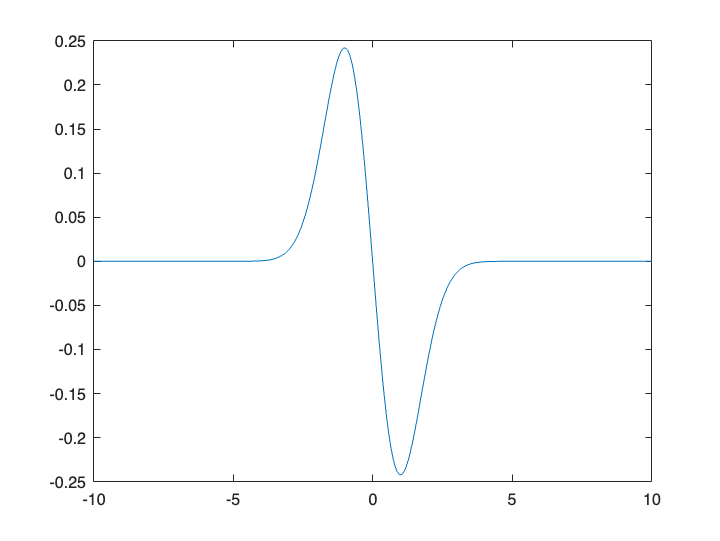


delta = 0.0136197916667;
der = (f(x+delta) - f(x))./delta;
plot(x, der)

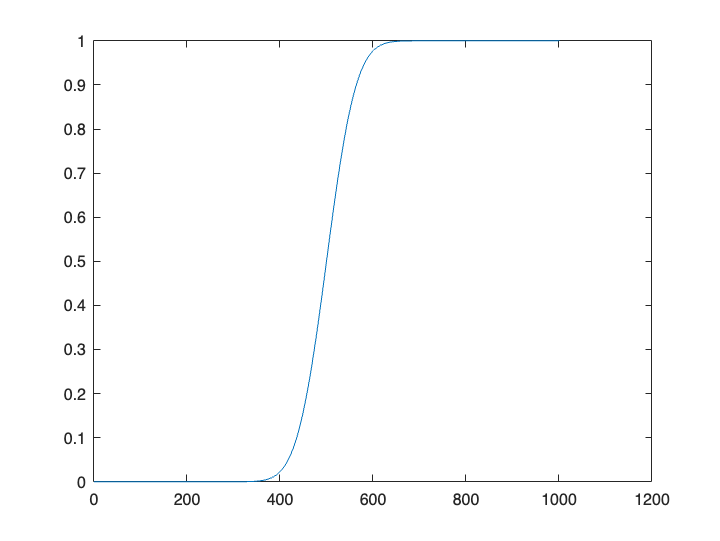


F = @(x) h.*cumsum(f(x));
plot(F(x))






array = 1:1:100;
output = 0;
for i = array
    output = output + i;
end

output

output =         5050



fb = [0,1]

fb =      0     1




for i = 3:21
    fb = [fb, fb(i-1)+fb(i-2)];
end

fb

fb =            0           1           1           2           3           5           8          13          21          34          55          89         144         233         377         610         987        1597        2584        4181        6765



x = 0

x =      0


output = 0

output =      0


while x < 100
    x = x+1;
    output = output + x;
end
output

output =         5050



v =[13, 42, 222, 87, 63];
a = 1

a =      1


for i = 1:length(v)
    a = a*v(i)
end

a =     13


a =    546


a =       121212


a =     10545444


a =    664362972


a

a =    664362972


function [x] = new_function(v, w)
 % You can assume that v and w are sorted vectors
    while v(1)~=(w(2)+1)
        if v(1)<(w(2)+1)
            v(1) = [ ];
        elseif v(1)>(w(2)+1)
            w(2) = [ ];
        end
    end
    x = v(1);
end

x = new_function([1,2,3,4],[4,3,2,1])

x = 4


(1+6)/2

ans = 3.5000


function [xb] = fnl(y, err)
% y and err should be positive real numbers.
    x0 = 1;
    x1 = 2*y;
    xb = (x0+x1)/2;
    n = 0
    while abs (xb-y) >err 
        if xb<y
            x0 = xb;
        elseif xb>y
            x1 = xb;
        end
        xb = (x0+x1)/2
        n = n+1
    end
end

[xb] = fnl(3,0.01)

n = 0

xb = 2.2500

n = 1

xb = 2.8750

n = 2

xb = 3.1875

n = 3

xb = 3.0312

n = 4

xb = 2.9531

n = 5

xb = 2.9922

n = 6

xb = 2.9922


function a = rw_test(n)
    position = 0;
    a = [0];
    for i = 1:n
        position = position + randi(2)*2-3;
        a = [a, position];
    end
end
a = rw_test(3)

a =      0    -1     0     1
